# Minimum Actuation Time - Task 2

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs


### 1) Trajectory Planning



dS = norm(P2-P1);

% Alfa
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
% Beta
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
% Rho
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);


n = 100;
dT = T/(n-1);

### 1) Kinematics - gripper coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


Calculate the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


for i = 1:1:length(s)

Unrecognized function or variable 'T'.

    t = (i-1)*dT;
    tt(i) = t;
    if i==1
        guess = [130*pi/180 50*pi/180];
    else
        guess = q(i-1,:);
    end
    q(i,:) = inverse_kinematics(s(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s(i,:),q(i,:),L);
    qp(i,:) = J*v(i,1:2)';
    qpp(i,:) = -inv(J_q)*((Jp_s(q(i,:),qp(i,:),v(i,1:2),L)*v(i,1:2)'+J_s*a(i,1:2)'+Jp_q(s(i,:),q(i,:),qp(i,:),v(i,1:2),L)*qp(i,:)'));
    
end



### 3D Plot

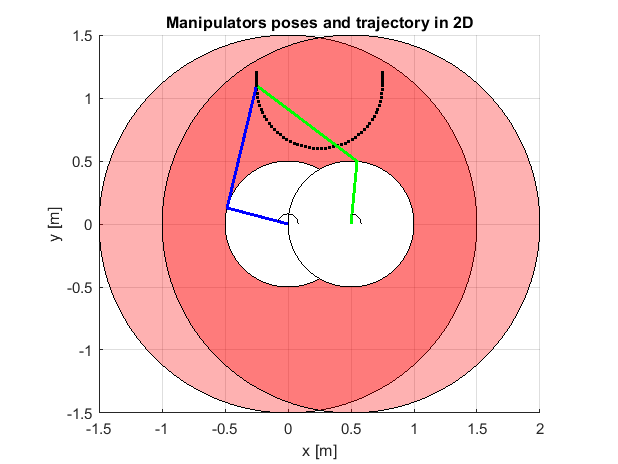

close all

figure(2)
plot3(0,0,0,'LineWidth',4,'color','red') 
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+l2]);
zlim([0,h]);
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on
for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dT)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end
hold off



### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

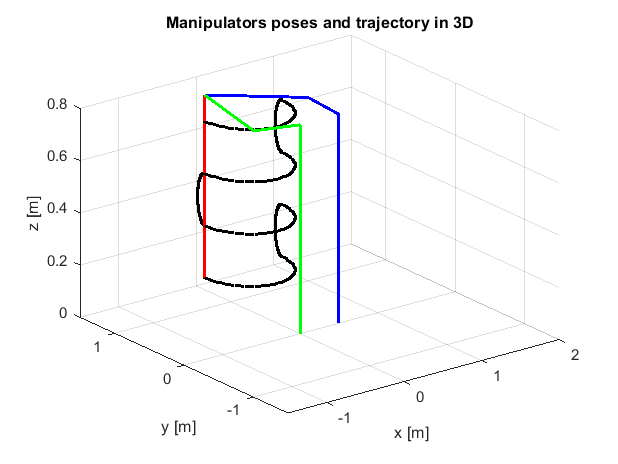

figure(4)

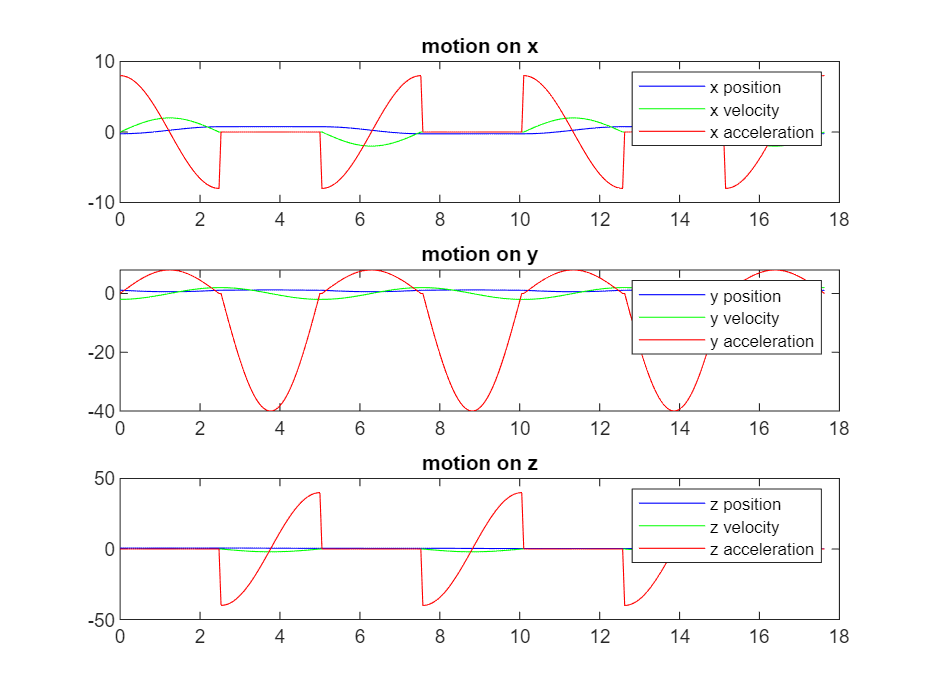

% alpha e beta
subplot(1,2,1)

plot(q(:,1)*180/pi,'b','LineWidth',2);
hold on
plot(q(:,2)*180/pi,'g','LineWidth',2);
hold off
title('Active Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint alfa','Joint beta')

% gamma e theta
subplot(1,2,2)
plot(gamma*180/pi,'LineWidth',2);
hold on
plot(theta*180/pi,'LineWidth',2);
hold off
title('Passive Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint gamma','Joint theta')

### 1b) Joint motion

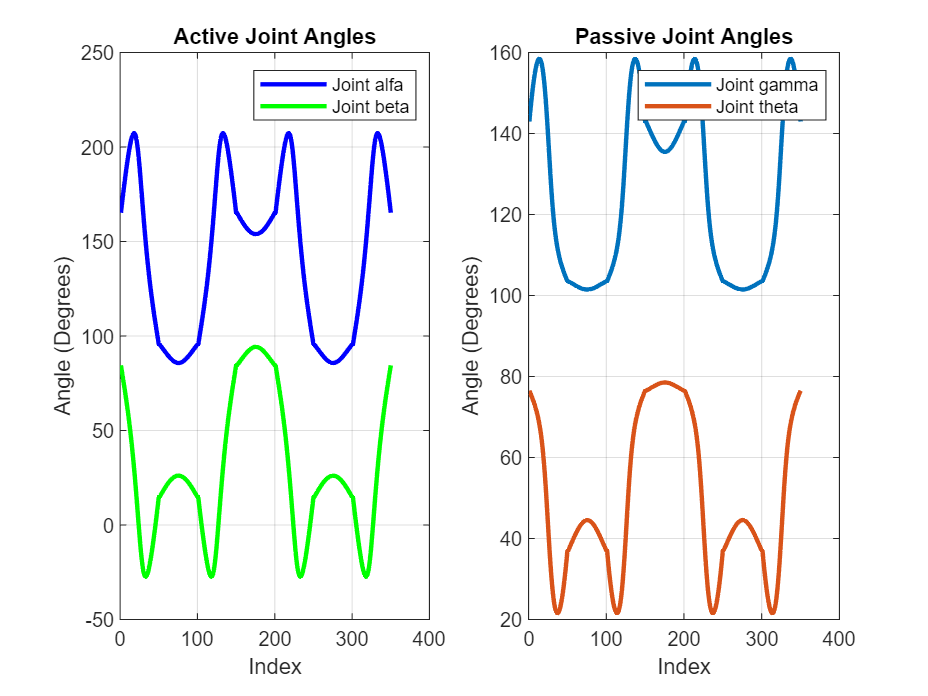

figure(5)
qp_alfa_debug = diff(q(:,1))/dT;
qp_beta_debug = diff(q(:,2))/dT;

qpp_alfa_debug = diff(qp(:,1))/dT;

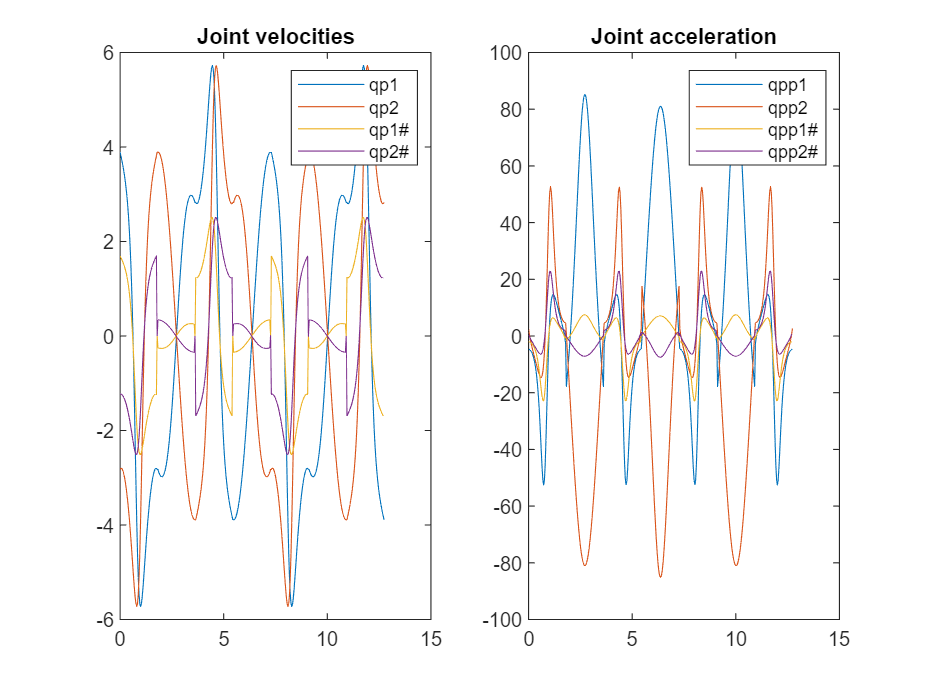

qpp_beta_debug = diff(qp(:,2))/dT;

subplot(1,2,1)
plot(tt,qp(:,1),tt,qp(:,2),tt(1:end-1),qp_alfa_debug,tt(1:end-1),qp_beta_debug);
legend('qp1','qp2','qp1#','qp2#');
title('Joint velocities')
subplot(1,2,2)
plot(tt,qpp(:,1),tt,qpp(:,2),tt(1:end-1),qpp_alfa_debug,tt(1:end-1),qpp_beta_debug);
legend('qpp1','qpp2','qpp1#','qpp2#')
title('Joint acceleration')